clc;
close all;
clear;
load("robot.mat");

Initial: 240,0,230

Intermediate: 100,-100,265

Final: 160,160,100

d1 = 0.128;
a1 = 0.029; 
a2 = 0.108; 
a3 = 0.02; d4 = 0.168;
d6 = -0.02429;
dhparams = [0,   	   0,    	d1,      0;
            a1,       -pi/2,    0,       0;
            a2,        0,    	0,       0;
            a3,       -pi/2,    d4,      0;
            0,         pi/2,    0,       0;
            0,         pi/2,    d6,      0];

ee_guessinit = [0,0,0,0,0,0];
ee_init = [0,23.1,-25.7,0,2.6,0];
ee_init = ee_init*pi/180;
ee_inter = [-44.9,-25.1,9.7,0,15.4,44.9];
ee_inter = ee_inter*pi/180;
ee_final = [44.9,31.0,9.8,0,-40.8,-44.9];
ee_final = ee_final*pi/180;

#### angle transform

homeconfig = homeConfiguration(robot);
initconfig = homeconfig + ee_init';
interconfig = homeconfig + ee_inter';
finalconfig = homeconfig + ee_final';
% Initial = homeconfig + ee_init';
% Intermediate = homeconfig + ee_inter';
% Final = homeconfig + ee_final';

%% Iterative Inverse Kinematics
syms th1 th2 th3 th4 th5 th6

T01 = dh_transmatrix(0,0,d1,th1);
T12 = dh_transmatrix(a1,-pi/2,0,th2);
T23 = dh_transmatrix(a2,0,0,th3);
T34 = dh_transmatrix(a3,-pi/2,d4,th4);
T45 = dh_transmatrix(0,pi/2,0,th5);
T56 = dh_transmatrix(0,pi/2,d6,th6);

T06 = T01 * T12 * T23 * T34 * T45 * T56;
T = simplify(T06);

Q_t = T(1:3,4);                               % Translation Vector
JQ = jacobian(Q_t,[th1,th2,th3,th4,th5,th6]);             % Jacobian Matrix 

P1 = subs(Q_t,th1,interconfig(1));            % Substitute each angle from symbol to number in initial condition. 
P2 = subs(P1,th2,interconfig(2));
P3 = subs(P2,th3,interconfig(3));
P4 = subs(P3,th4,interconfig(4));
P5 = subs(P4,th5,interconfig(5));
P6 = subs(P5,th6,interconfig(6));
p_target_inter = double(P6);                       % Calculating the final position from given final angle, convert from symbolic type to double type.

P1 = subs(Q_t,th1,finalconfig(1));
P2 = subs(P1,th2,finalconfig(2));
P3 = subs(P2,th3,finalconfig(3));
P4 = subs(P3,th4,finalconfig(4));
P5 = subs(P4,th5,finalconfig(5));
P6 = subs(P5,th6,finalconfig(6));
p_target_final = double(P6);  

theta_k_1 = initconfig;                   % Initial interative, note that since you have four rows, the homeconfig is a 4 by 1 vector, we only need first 3 elements            

%% Newton Raphson's loop

constraint_theta = [-110,    160;
                    -35-90,  70-90;
                    -120,    60;
                    -180,     180;
                    -200+90, 30+90;
                    -360,    360] %Angle constraints

constraint_theta =   -110   160
  -125   -20
  -120    60
  -180   180
  -110   120
  -360   360


constraint_theta = constraint_theta/180*pi;

Q1 = subs(Q_t,th1,theta_k_1(1));
Q2 = subs(Q1,th2,theta_k_1(2));
Q3 = subs(Q2,th3,theta_k_1(3));
Q4 = subs(Q3,th4,theta_k_1(4));
Q5 = subs(Q4,th5,theta_k_1(5));
Q6 = subs(Q5,th6,theta_k_1(6));
Q_k_1 = double(vpa(Q6,12)); % Translation vector for theta_k_1, Convert from symbolic to numeric 

p_number = 5; %split the path
target_points_init_to_inter = split_target_points(Q_k_1,p_target_inter,p_number);
target_points_inter_to_final = split_target_points(p_target_inter,p_target_final,p_number);
target_points_inter_to_final(:,1) = [];
target_points = cat(2,target_points_init_to_inter,target_points_inter_to_final);

theta_list = theta_k_1;     
for j = 2:length(target_points)
    Vp_to_target = target_points(:,j)-target_points(:,j-1);
    p_to_target = norm(Vp_to_target); % Distance between target position and guess 
    
    while p_to_target > 0.0001  
        p_to_target_pre = p_to_target;
        J0 = subs(JQ,th1,theta_k_1(1));
        J1 = subs(J0,th2,theta_k_1(2));
        J2 = subs(J1,th3,theta_k_1(3));
        J3 = subs(J2,th4,theta_k_1(4));
        J4 = subs(J3,th5,theta_k_1(5));
        J5 = subs(J4,th6,theta_k_1(6));
        Jacob = double(vpa(J5,12));       % Jacobian for theta_k_1, Convert from symbolic to numeric       
        Jinv = pinv(Jacob);

        theta_k = theta_k_1 + Jinv * Vp_to_target;     % Using the iterative method
    
        for i = 1:size(theta_k,1)                                        % Angle Constrains 
            theta_k(i) = max(min(theta_k(i), constraint_theta(i,2)),constraint_theta(i,1));    
        end
    
        theta_list = [theta_list, theta_k];     

        Q1 = subs(Q_t,th1,theta_k(1));
        Q2 = subs(Q1,th2,theta_k(2));
        Q3 = subs(Q2,th3,theta_k(3));
        Q4 = subs(Q3,th4,theta_k(4));
        Q5 = subs(Q4,th5,theta_k(5));
        Q6 = subs(Q5,th6,theta_k(6));
        Q_k = double(vpa(Q6,12));         % Translation vector for newly computed theta_k, Convert from symbolic to numeric   
       
        if (Vp_to_target > Q_k_1 - Q_k)
            target_points(:,j) = Q_k_1;  
        end
        Vp_to_target = target_points(:,j)-Q_k;         % vector from estimated position to desired target position
        p_to_target = norm(Vp_to_target);     
        p_to_target
        theta_k_1 = theta_k; 
        Q_k_1 = Q_k;   
       
%         if (abs(p_to_target_pre-p_to_target)/p_to_target_pre) < 0.001
%             break;
%         end
    end
    target_points(:,j) = Q_k; 
end

p_to_target = 0.0041

p_to_target = 4.7560e-05

p_to_target = 0.0040

p_to_target = 4.3048e-05

p_to_target = 0.0040

p_to_target = 4.6545e-05

p_to_target = 0.0042

p_to_target = 6.2528e-05

p_to_target = 0.0044

p_to_target = 8.1130e-05

p_to_target = 0.0152

p_to_target = 0.0128

p_to_target = 4.4228e-04

p_to_target = 2.3396e-07

p_to_target = 0.0153

p_to_target = 0.0153

p_to_target = 7.0023e-04

p_to_target = 9.1273e-06

p_to_target = 0.0158

p_to_target = 0.0011

p_to_target = 4.8036e-06

p_to_target = 0.0166

p_to_target = 8.8889e-04

p_to_target = 3.0641e-06

p_to_target = 0.0160

p_to_target = 0.0162

p_to_target = 7.5805e-04

p_to_target = 2.0227e-06

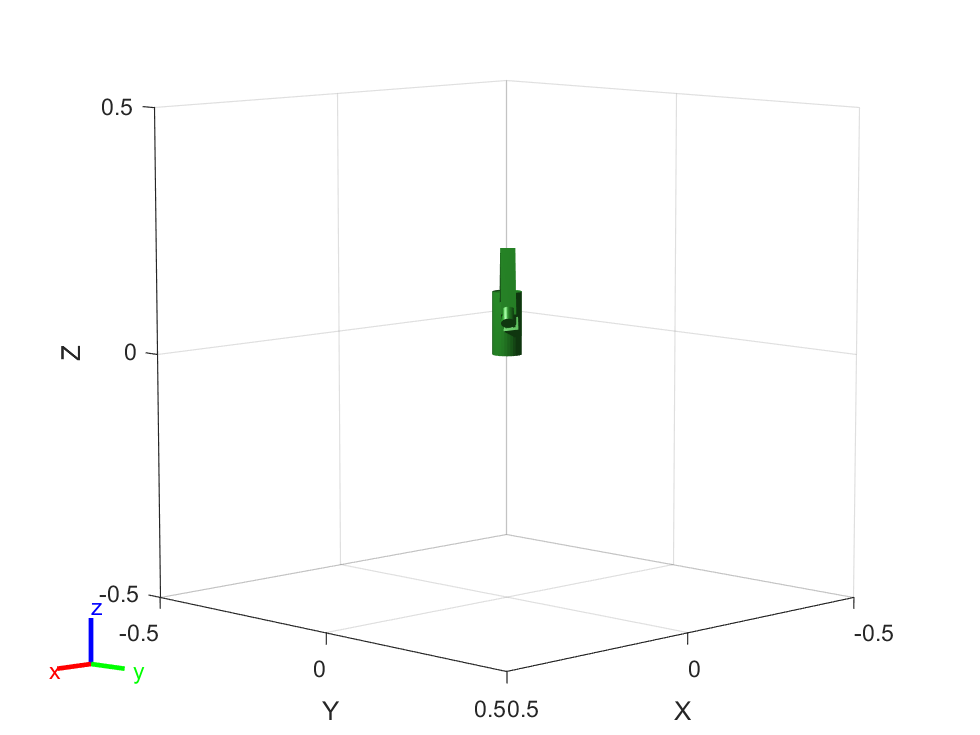

%% Robot Simulation & Creating Video
Initial = homeconfig;
Step = 2;
framesPerSecond = 10;
cnt = 1;
for j = 2 : length(theta_list)
    Qd = theta_list(:,j) - theta_list(:,j-1);
    for i = 1:Step
        q = theta_list(:,j-1) + Qd / Step * i;
        show(robot,q,"Collisions","on","Frames","off");
        F(cnt) = getframe(gcf) ;
        cnt = cnt+1;
        drawnow
    end

end


% create the video writer with 1 fps
writerObj = VideoWriter('Task3.avi');
writerObj.FrameRate = 10;
% set the seconds per image
% open the video writer
open(writerObj);
% write the frames to the video
for i=1:length(F)
    % convert the image to a frame
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
% close the writer object
close(writerObj);

function to split the path

function target_points = split_target_points(p_init,p_target,p_number)
target_points = zeros(3,p_number+1);
Vp_to_target = p_target-p_init; % total vector from guessed position to desired target position 
delta_p = Vp_to_target/p_number;
target_points(:,1) = p_init;
for i = 2:p_number+1
    target_points(:,i) = target_points(:,i-1)+delta_p;
end
end

function to calculate transform matrix according to one line of the MDH table

function T = dh_transmatrix(a,alpha,d,theta)
    T = [   cos(theta),             -sin(theta),            0,           a;
            sin(theta)*cos(alpha),  cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
            sin(theta)*sin(alpha),  cos(theta)*sin(alpha),  cos(alpha),  cos(alpha)*d;
            0,                      0,                      0,           1];
end